Aby to fungovalo, musí se přidat cesta, zároveň zavedeme nápovědu (stačí spustit na začátku relace jednou)

addpath(genpath('C:\Fyzing\Baka\MATLAB\MNPBEM17'));

run('C:\Fyzing\Baka\MATLAB\MNPBEM17/makemnpbemhelp.m')

Removing existing index directory at C:\Fyzing\Baka\MATLAB\MNPBEM17\help\helpsearch-v4_en
Process Duration: 0.001260
Successfully created search database.


clc 
clear all
close all

Set up the dielectric environment and options for BEM:

%  options for BEM simulation
opstat = bemoptions( 'sim', 'stat', 'interp', 'curv'  );
opret =  bemoptions( 'sim', 'ret', 'interp', 'curv' );
%  table of dielectric functions
epstab = { epsconst( 1),  epsdrude('myAg') };  %epstable( 'silver.dat' ) };

epsconst(1) ... dielectrc function of vacuum

p1 = trirod( 10, 30, [ 20, 10, 20 ] );
p1 = rot(p1, 90, [0,1,0]);
p1 = shift( p1, [ 0, 10 ,7.5 ] );

p2 = trirod( 10, 30, [ 20, 10, 20 ] );
p2 = rot(p2, 90, [1,0,0]);
p2 = shift( p2, [ 10, 0, -7.5 ] );

n1 for the circumference of the rod, n2 for the polar angles of the rod caps, n3 for the cylinder-shaped middle part of the rod, and

p = comparticle( epstab, { p1, p2 }, [ 2, 1; 2, 1 ], 1, 2, opret );

## Plot the particles

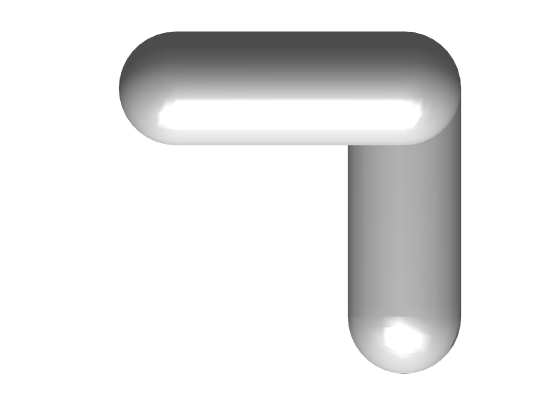

clf
plot( p, 'FaceColor', [1,1,1] );
xlim("auto")
ylim("auto")
zlim("auto")
view([0 90])

%view([90 0])
%view([-45 10.2])
%plot( p, 'EdgeColor', "b");
% plot( p, 'EdgeColor', 'b', 'nvec', 1 );

## Find the eigenmodes

nev = 20

nev = 20

bemeig = bemstateig(p, opstat, 'nev', nev);
% from the eigensolution, we can get the corresponding pseudocharges on the
% surface corresponding to different eigenmodes
eigencharges = bemeig.ur ;
eigenpseudolambdas = bemeig.ene ; %unit matrix with eigeneenrgies on diagonal
pfacepos = p.pos ;
pfacearea = p.area ;

save the eigenmodes

writematrix(eigencharges,"MY_PROJECTS\nanorods\eigencharges.csv")

Error using writematrix
Unable to open file 'MY_PROJECTS\nanorods\eigencharges.csv' for writing:

No such file or directory

writematrix(eigenpseudolambdas,"MY_PROJECTS\nanorods\eigenpseudolambdas.csv")
writematrix(pfacepos,"MY_PROJECTS\nanorods\pfacepos.csv")
writematrix(pfacearea,"MY_PROJECTS\nanorods\pfacearea.csv")

plot the eigencharges

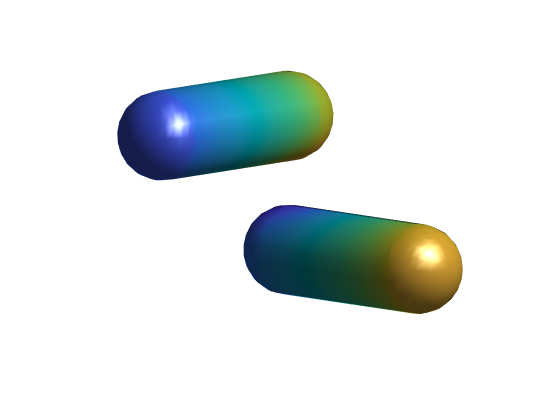

figure()
plot(p, eigencharges(:,3))
xlim("auto")
ylim("auto")
zlim("auto")
view([-45.7 8.8])

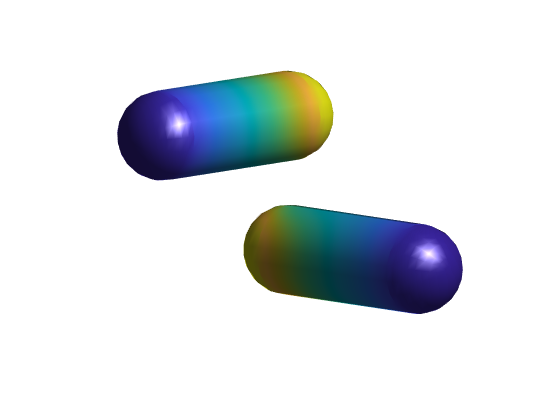

figure()
plot(p, eigencharges(:,4))
xlim("auto")
ylim("auto")
zlim("auto")
view([-45.7 8.8])

## EELS to find the right prefactor

%  width of electron beam and electron velocity
[ width, vel ] = deal( 0.3, 0.446 * 2.99792458e8 );
%  impact parameters 
[X, Y] = meshgrid(linspace(-40,40,70),linspace(-40,40,70));
imp = [ X(:) , Y(:) ]; %linspace( -30, 30, 32 );
%  loss energies in eV
ene = [ 2.764490219193807885e+00, 2.961953806279079782e+00 ];

ene =     2.7645    2.9620


%ene = linspace(2,4,21)
% ene = [4.2,  4.5] * 1e15 * 1.05457182e-34 / 1.602e-19 ; %linspace( 2.5, 4.5, 60 );

%  convert energies to nm
units;  enei = eV2nm ./ ene;

## Quasistatic

%%  BEM solution
%  BEM solver
bem = bemsolver( p, opstat );
%  electron beam excitation
exc = electronbeam( p, imp, width, vel, opstat );
%  surface and bulk losses
[ psurf, pbulk ] = deal( zeros( numel( imp(:,1) ), numel( enei ) ) );

multiWaitbar( 'BEM solver (quasistatic)', 0, 'Color', 'g', 'CanCancel', 'on' );
%  loop over wavelengths
for ien = 1 : length( enei )
  %  surface charges
  sig = bem \ exc( enei( ien ) );
  %  EELS losses
  [ psurf( :, ien ), pbulk( :, ien ) ] = exc.loss( sig );
  
  multiWaitbar( 'BEM solver (quasistatic)', ien / numel( enei ) );
end
%  close waitbar
multiWaitbar( 'CloseAll' );

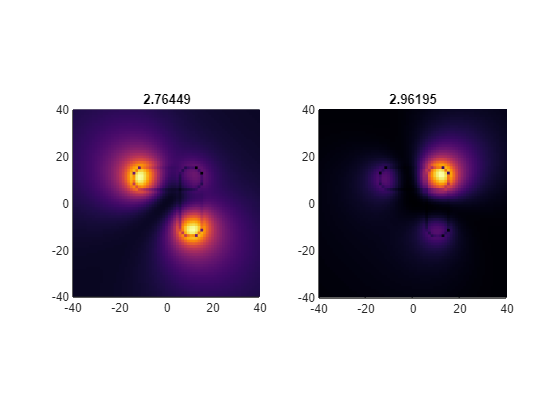

%%  final plot
%  electron energy loss probability
figure()
for i = 1:2
    subplot(1,2,i);
    pc = pcolor(X, Y, reshape(psurf(:,i) , size(X)) );
    pc.EdgeAlpha=0;
    colormap inferno;
    title(ene(i));
    axis square;

end

## Retarded

%%  BEM solution
%  BEM solver
bem = bemsolver( p, opret );
%  electron beam excitation
exc = electronbeam( p, imp, width, vel, opret );
%  surface and bulk losses
[ psurf, pbulk ] = deal( zeros( numel( imp(:,1) ), numel( enei ) ) );

multiWaitbar( 'BEM solver (retarded)', 0, 'Color', 'g', 'CanCancel', 'on' );
%  loop over wavelengths
for ien = 1 : length( enei )
  %  surface charges
  sig = bem \ exc( enei( ien ) );
  %  EELS losses
  [ psurf( :, ien ), pbulk( :, ien ) ] = exc.loss( sig );
  
  multiWaitbar( 'BEM solver (retarded)', ien / numel( enei ) );
end
%  close waitbar
multiWaitbar( 'CloseAll' );

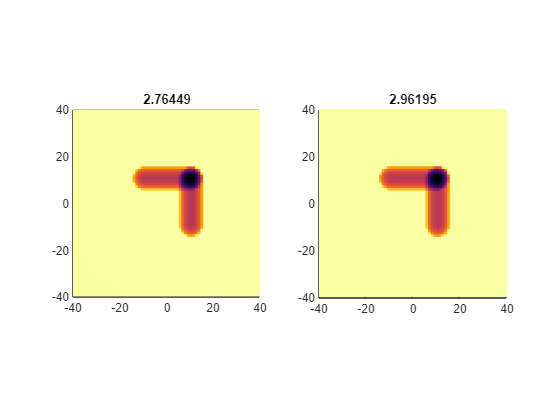

%%  final plot
%  electron energy loss probability
figure()
for i = 1:2
    subplot(1,2,i);
    pc = pcolor(X, Y, reshape(psurf(:,i) , size(X)) );
    pc.EdgeAlpha=0;
    colormap inferno;
    title(ene(i));
    axis square;

end

## Comparison of quasistatic and retarded calculation in spectra for a few points

For particles with following parameters 

We get different spectra using quasistatic /  retarded calculations

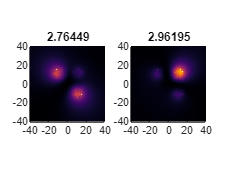 / 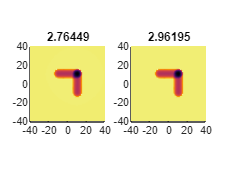

We will thus map the "full" spectra in a few points: 

%%  width of electron beam and electron velocity
[ width, vel ] = deal( 0.3, 0.446 * 2.99792458e8 );
%%  impact parameters 
imp =  [[0,0],
        [15,15],
        [15,-20]];
%% loss energies in eV
% ene = [ 2.764490219193807885e+00, 2.961953806279079782e+00 ]
ene = linspace(2,3,50);
% ene = [4.2,  4.5] * 1e15 * 1.05457182e-34 / 1.602e-19 ; %linspace( 2.5, 4.5, 60 );

%  convert energies to nm
units;  enei = eV2nm ./ ene;

%% Quasistatic BEM solution
%  BEM solver
bem = bemsolver( p, opstat );
%  electron beam excitation
exc = electronbeam( p, imp, width, vel, opstat );
%  surface and bulk losses
[ psurfstat, pbulkstat ] = deal( zeros( numel( imp(:,1) ), numel( enei ) ) );

multiWaitbar( 'BEM solver (stat)', 0, 'Color', 'g', 'CanCancel', 'on' );
%  loop over wavelengths
for ien = 1 : length( enei )
  %  surface charges
  sig = bem \ exc( enei( ien ) );
  %  EELS losses
  [ psurfstat( :, ien ), pbulkstat( :, ien ) ] = exc.loss( sig );
  
  multiWaitbar( 'BEM solver (stat)', ien / numel( enei ) );
end
%  close waitbar
multiWaitbar( 'CloseAll' );

%% retarded BEM solution
%  BEM solver
bem = bemsolver( p, opret );
%  electron beam excitation
exc = electronbeam( p, imp, width, vel, opret );
%  surface and bulk losses
[ psurfret, pbulkret ] = deal( zeros( numel( imp(:,1) ), numel( enei ) ) );

multiWaitbar( 'BEM solver (ret)', 0, 'Color', 'g', 'CanCancel', 'on' );
%  loop over wavelengths
for ien = 1 : length( enei )
  %  surface charges
  sig = bem \ exc( enei( ien ) );
  %  EELS losses
  [ psurfret( :, ien ), pbulkret( :, ien ) ] = exc.loss( sig );
  
  multiWaitbar( 'BEM solver (ret)', ien / numel( enei ) );
end
%  close waitbar
multiWaitbar( 'CloseAll' );

Plotting the spectra:

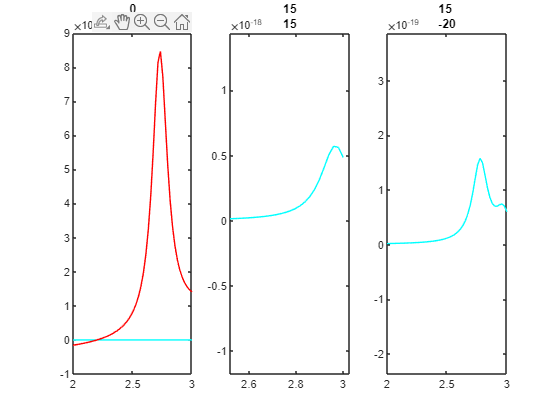

clf
figure()
for iimp = 1:length(imp)
    subplot(1,length(imp),iimp)
    plot(ene, psurfstat(iimp,:),"Color",[0 1 1])
    hold on
    plot(ene, psurfret(iimp,:),"Color",[1 0 0])
    title(imp(iimp,:))
end

pcolor(X, Y, reshape(psurf(:,i) , size(X)) )
imagesc( ene, imp, psurf + pbulk );  hold on

set( gca, 'YDir', 'norm' );
colorbar

xlabel( 'Loss energy (eV)' );
ylabel( 'x (nm)' );

title( 'Loss probability (eV^{-1})' );